# **Submitted by:**

# **Puneet Singh Arora -  1056132**

## **TASK OUTLINE**

- Completion of the Live Script

- Documenting the Live script and explaining the code logic theoratically.

- Classify Human Activity by using Wavelet Analysis and Deep Learning Algorithms performed on accelertion measurements/data acquired from our mobile phones and building a datastore in matlab as such.

Now here the goal of this classification using Wavelet analysis is to classify the set of given accelerometer signal into one of the appropriate 3 classes. 

- Sitting

- Walking

- Running

After that this created database will be analysed using wavelet analysis. Subsequently, a CNN will be designed for classifying accurately

The resulting CNNs created will be used to classify the given accelerometer signal to either of the three appropriate classes. 

- Analyse the datastore/training data using Wavelet Analysis (Scalograms)

- Design a CNN (e.g. pretrained GoogLeNet) for the classification

%Creating a function for classification
close all;
clear all;
%function classify_sitting_data including mat_file_path

## **Loading our individual datasets into the matlab environment**

% Loading each dataset created into the matlab environment
S_data = load('/Users/karan/Desktop/Training data/MobileSensorData/Sitting data.mat');
S_data = S_data.Acceleration

S_data = 34276×3 timetable
           Timestamp                X           Y         Z   
    ________________________    _________    _______    ______

    27-Sep-2024 20:23:05.950    -0.054187    0.18038     9.762
    27-Sep-2024 20:23:05.968    -0.060474    0.16436    9.7513
    27-Sep-2024 20:23:05.985    -0.055984    0.18502    9.7515
    27-Sep-2024 20:23:06.003    -0.061372     0.1931    9.7465
    27-Sep-2024 20:23:06.020    -0.071402    0.17768    9.7464
    27-Sep-2024 20:23:06.038    -0.056433    0.17663    9.7573
    27-Sep-2024 20:23:06.055    -0.053439     0.1666    9.7413
    27-Sep-2024 20:23:06.073    -0.057031    0.17304    9.7627
    27-Sep-2024 20:23:06.090    -0.056133    0.17888 

W_data = load('/Users/karan/Desktop/Training data/MobileSensorData/Walking data.mat');
W_data = W_data.Acceleration

W_data = 40022×3 timetable
           Timestamp               X          Y         Z   
    ________________________    ________    ______    ______

    28-Sep-2024 21:01:29.907    -0.54502    2.3206    9.9455
    28-Sep-2024 21:01:29.922     -0.5296    2.1944    9.8988
    28-Sep-2024 21:01:29.937    -0.46942    2.2031    9.7822
    28-Sep-2024 21:01:29.952    -0.56058    1.9784    9.9079
    28-Sep-2024 21:01:29.967    -0.61238    1.6645    10.109
    28-Sep-2024 21:01:29.982    -0.69216    1.3694    10.629
    28-Sep-2024 21:01:29.997    -0.80742    1.1071    11.174
    28-Sep-2024 21:01:30.012     -0.8896    1.1331    11.176
    28-Sep-2024 21:01:30.027    -0.87328    1.2743    11.513
    

R_data = load('/Users/Puneet/Desktop/Training data/MobileSensorData/Running data.mat');
R_data = R_data.Acceleration

R_data = 39961×3 timetable
           Timestamp               X           Y          Z   
    ________________________    ________    ________    ______

    29-Sep-2024 18:14:24.580     -1.7862     0.58543    12.446
    29-Sep-2024 18:14:24.595     -1.4996    0.067061     11.82
    29-Sep-2024 18:14:24.610    -0.51313     0.90143    10.764
    29-Sep-2024 18:14:24.625    -0.85218      1.8561    9.5585
    29-Sep-2024 18:14:24.640     -1.6249      2.5119    8.5748
    29-Sep-2024 18:14:24.655     -1.8049      2.5949    8.3163
    29-Sep-2024 18:14:24.670     -2.0259      2.6016    8.1242
    29-Sep-2024 18:14:24.685      -2.229      2.1693    8.2571
    29-Sep-2024 18:14:24.700     -1.7972      1.0257 

## **Combining the dataset to form a single dataset and visualizing the dataset in the Time-Frequency domain**

% Now here we are combining the three tables/datasets/signals in order to create a singular database
% for our analysis and classification
C_data = [S_data; W_data; R_data];

% Time Signal (t) Definition

fs=60; % sampling frequency of the signal as created in matlab
t = [0:length(C_data.Z)-1] /fs;

% Plot the accelerometer signal for the entire data range
figure;
subplot(2,1,2); % First plot for Accelerometer signal
plot(t,C_data.Z);
title('Accelerometer signal'); % title of the plot
xlabel('Time (s)');            % x-axis header
ylabel('Amplitude (units)');   % y-axis header


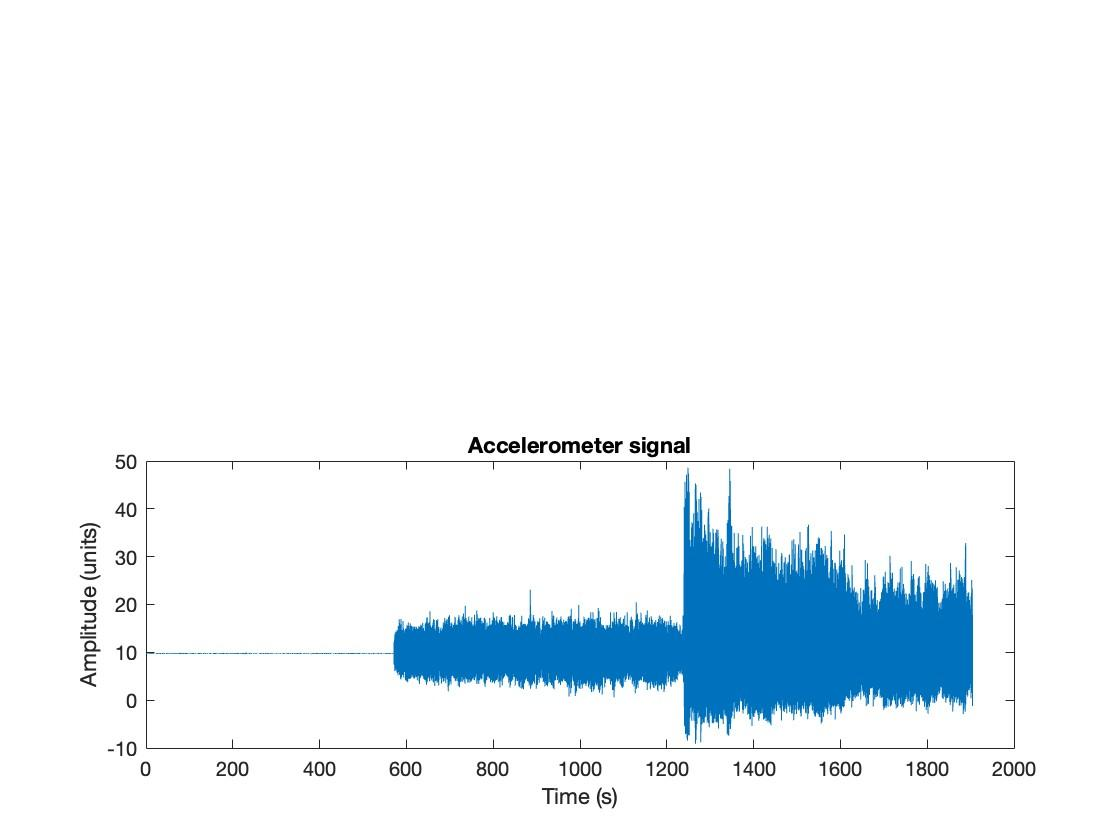

**Below code steps can be executed for further streamlining the signal as a part of data preprocessing for feeding noise free data (to certain extent) into CNN. Since we are able to achieve good accuracy results so not required in our case.**


% Calculate absolute acceleration by logically performing Pythagoras
% theoram over individual streams of datasets/signal
S_Accel = sqrt(S_data.X.^2 + S_data.Y.^2 + S_data.Z.^2);
W_Accel = sqrt(W_data.X.^2 + W_data.Y.^2 + W_data.Z.^2);
R_Accel = sqrt(R_data.X.^2 + R_data.Y.^2 + R_data.Z.^2);


% Normalize acceleration data (z-score normalization),Scaling
% Reducing the effect of outliers, hence improving model interpretability: 
Si_Accel = (S_Accel - mean(S_Accel)) / std(S_Accel);
Wa_Accel = (W_Accel - mean(W_Accel)) / std(W_Accel);
Ru_Accel = (R_Accel - mean(R_Accel)) / std(R_Accel);

% combined dataset Variable for Second CNN, a dataset for performing CWT
% upon and generating training data
C_Accel= {Si_Accel, Wa_Accel, Ru_Accel};

% Smooth data (optional - reduces noise)
%windowSize = 5; % Adjust the window size if needed
%sittingAccel = movmean(S_Accel, windowSize);
%walkingAccel = movmean(W_Accel, windowSize);
%runningAccel = movmean(R_Accel, windowSize);

## **Below we have created necessary scalograms for further analysing the signal trends along all 3 accelerometer axis**

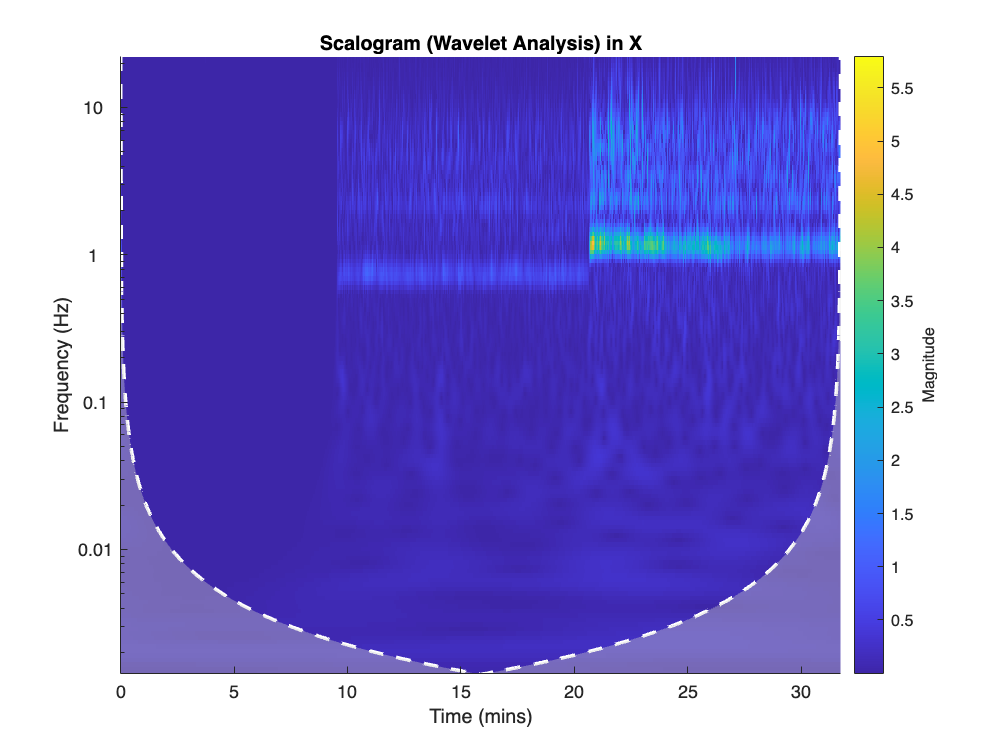

% Plot Scalogram using Continuous Wavelet Transform (CWT)
subplot(2,1,1); % Second plot for Scalogram
% Here we have used Morlet wavelet specifically for oscillatory acceleromter
% signal to increase accuracy. Another option is Morse wavelet or 'morse' which is a default
% value
cwt(C_data.X,'amor',fs);
title('Scalogram (Wavelet Analysis) in X');

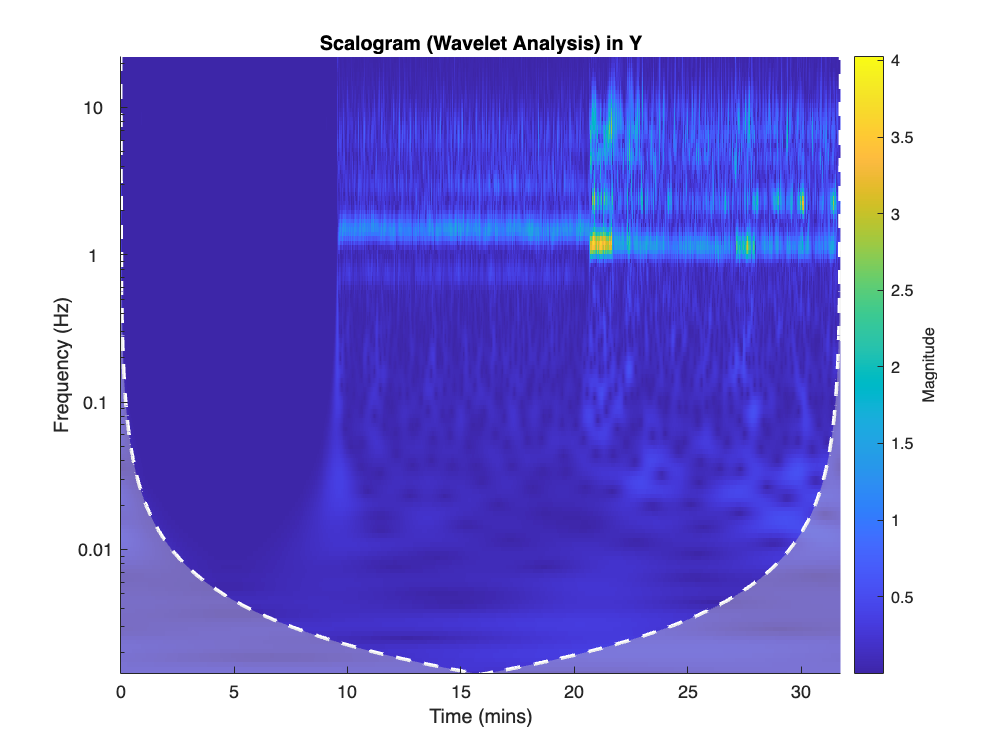

% CWT along Y axis
cwt(C_data.Y, 'amor', fs);
title('Scalogram (Wavelet Analysis) in Y');

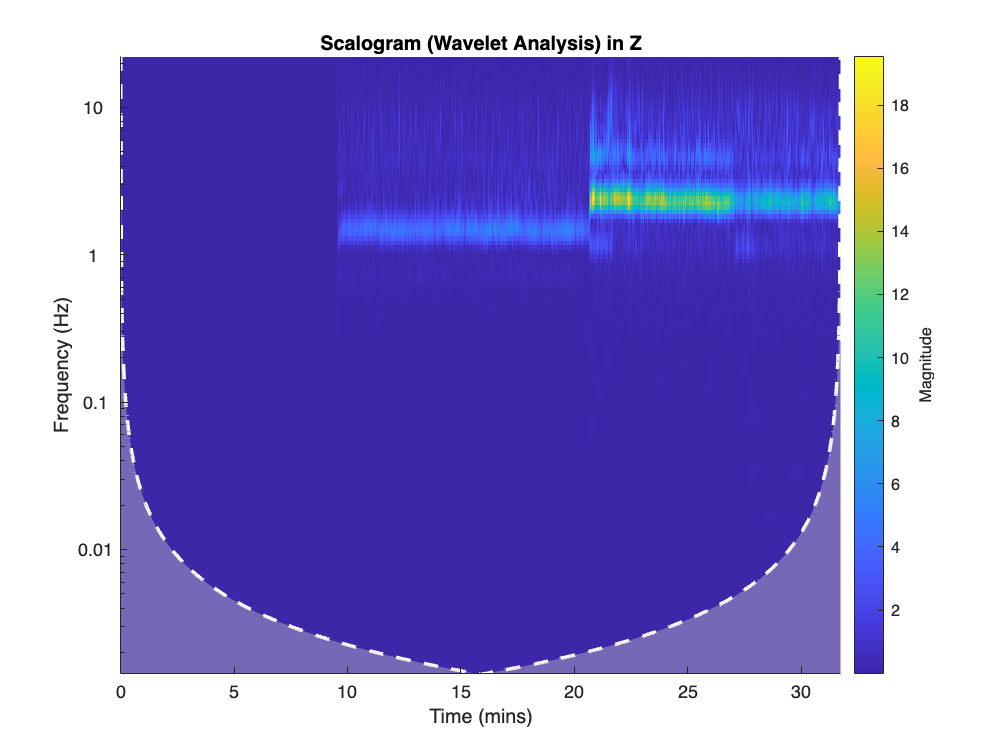

% CWT along z axis
cwt(C_data.Z, 'amor', fs);
title('Scalogram (Wavelet Analysis) in Z');

## 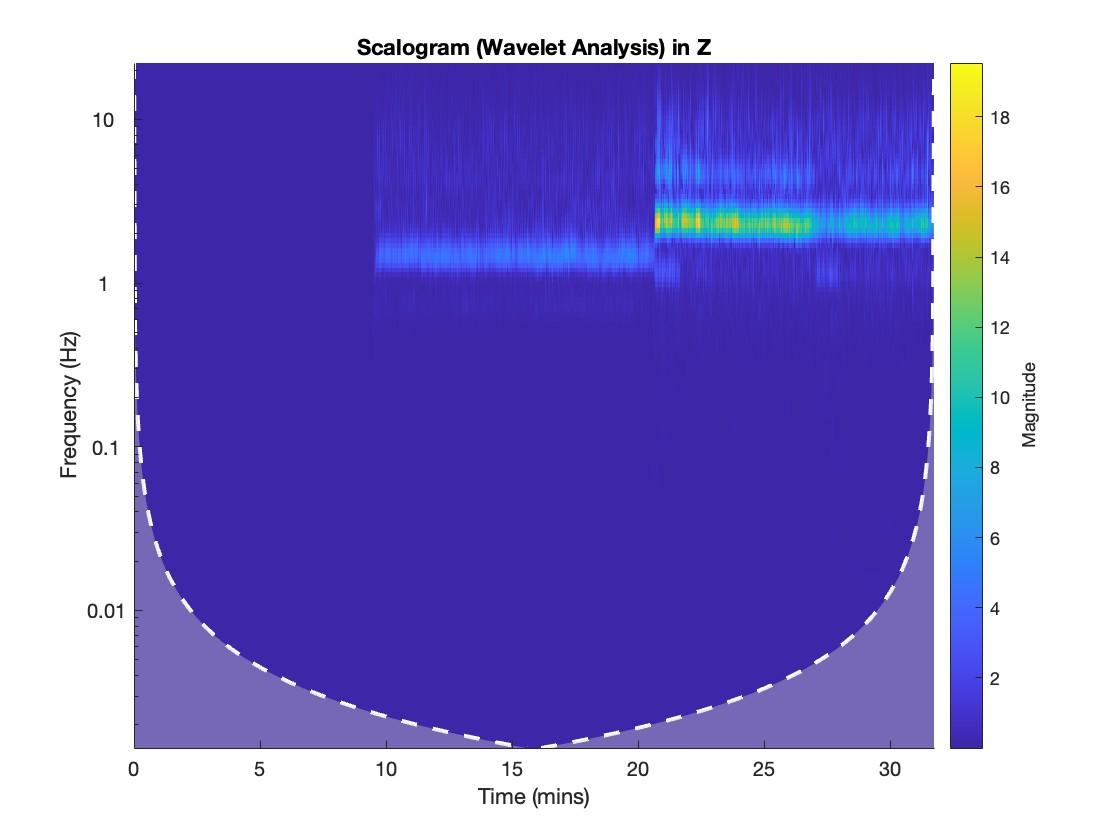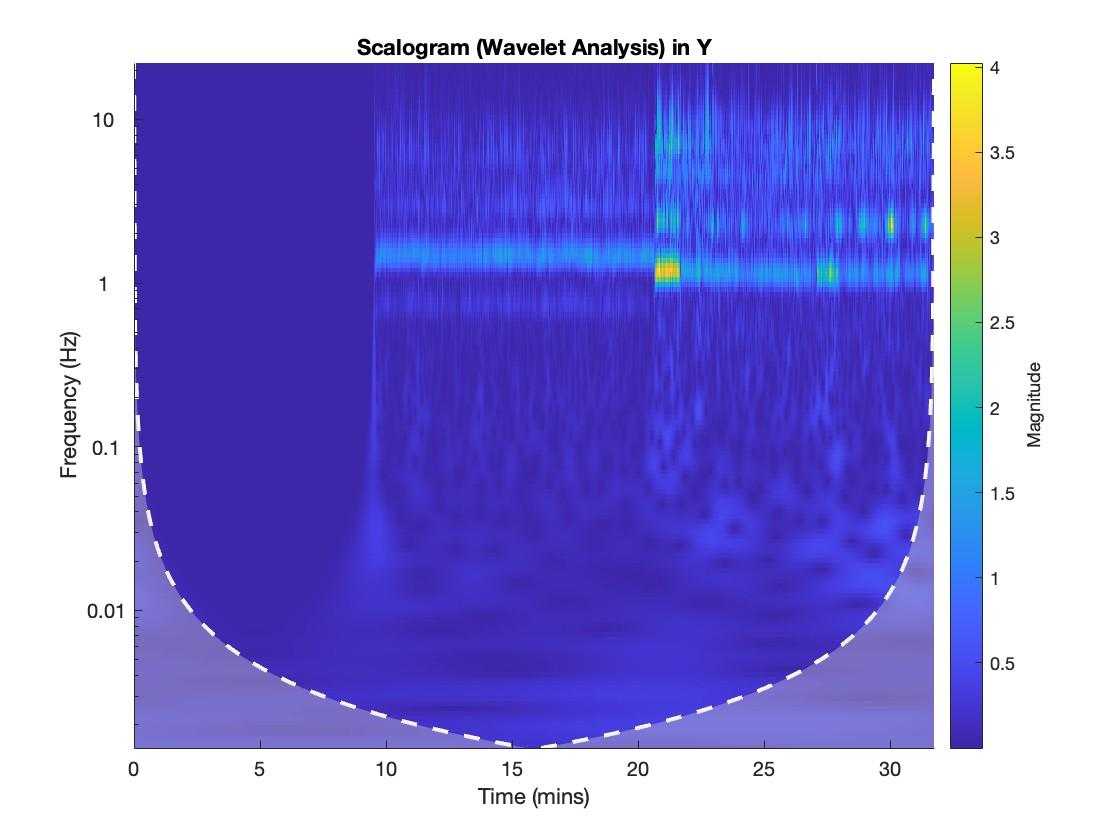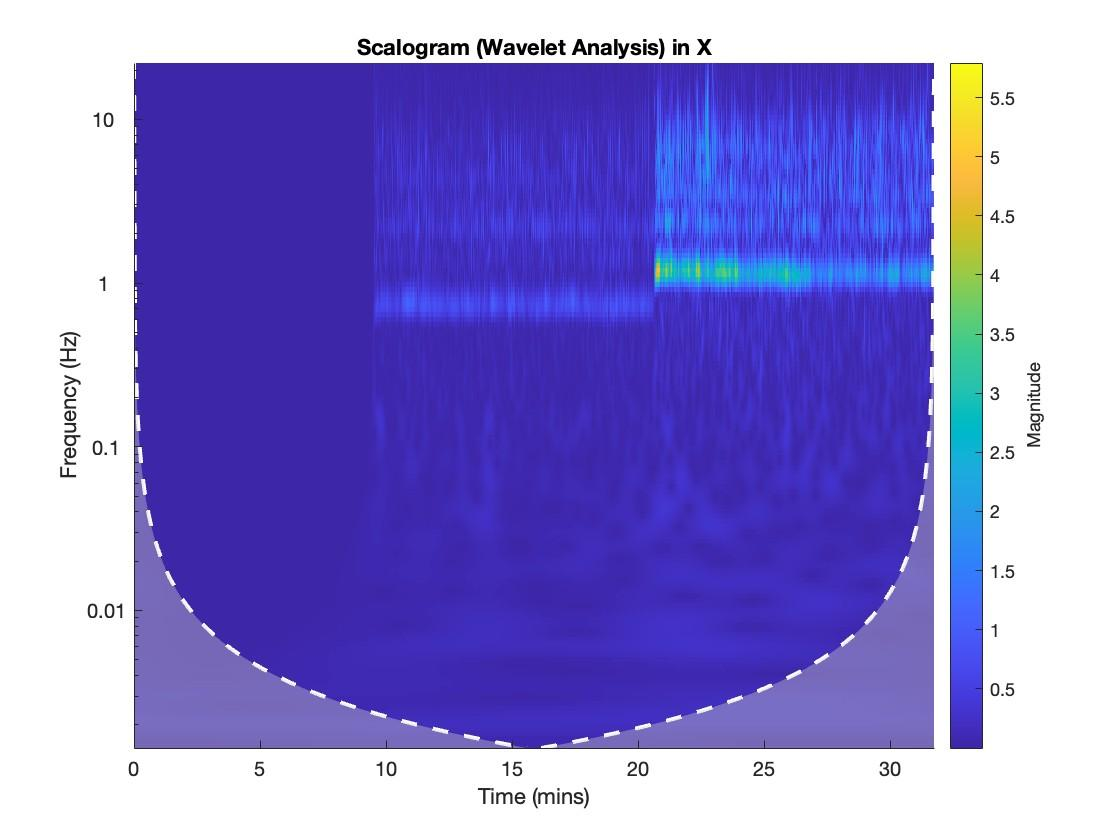

## **Now below we have performed Data Preprocessing , assigning appropriate classification labels for segregating the signals and created necessary datastores.**


% Assigning appropriate labels for the combined dataset to create a
% distinction for every individual signal
labels = [ones(size(S_data, 1), 1); 2*ones(size(W_data, 1), 1); 3*ones(size(R_data, 1), 1)];

%Creating data blocks among the total dataset 
Sitting= C_data(1:34276,:);  
Walking= C_data(34277:74298,:);
Running= C_data(74299:114259,:); 

%{
Now we can break these signals into smaller parts to further 
increase size of database
%}
signallength = 1000;

%{
%Creating necessary folders for CWT data/image creation

mkdir('/Users/karan/Desktop/Training data/CWTdata'); % Main folder
mkdir('/Users/karan/Desktop/Training data/CWTdata/sitting'); %sub folder for sitting data
mkdir('/Users/karan/Desktop/Training data/CWTdata/walking'); %sub folder for walking data
mkdir('/Users/karan/Desktop/Training data/CWTdata/running'); %sub folder for running data


Here we break each signal into overlapping segments. 
This step is considered basically as data augmentation so that CNN have
more and variable test data to work with
%}

% Here we define filters for CWT with Morlet wavelet and 15 filters per
% octave, if increase the value '15' to a bigger number there is a chance
% of overfitting and missing resolution of the signal. We again are using a
% Morlet wavelet

fb = cwtfilterbank('SignalLength', signallength, 'Wavelet', 'amor', 'VoicesPerOctave', 15);

signaltype = {'sitting','walking','running'};
folderpath = {'/Users/karan/Desktop/Training data/CWTdata/sitting', ...
               '/Users/karan/Desktop/Training data/CWTdata/walking', ...
               '/Users/karan/Desktop/Training data/CWTdata/running'};


%cwt
acc2cwtscg(Sitting, fb, signaltype{1});
acc2cwtscg(Walking, fb, signaltype{2});
acc2cwtscg(Running, fb, signaltype{3});


## **Function definition for creating RGB images out of the accelerometer dataset in specific directories which we will use for both training our CNN and validating its performance.**

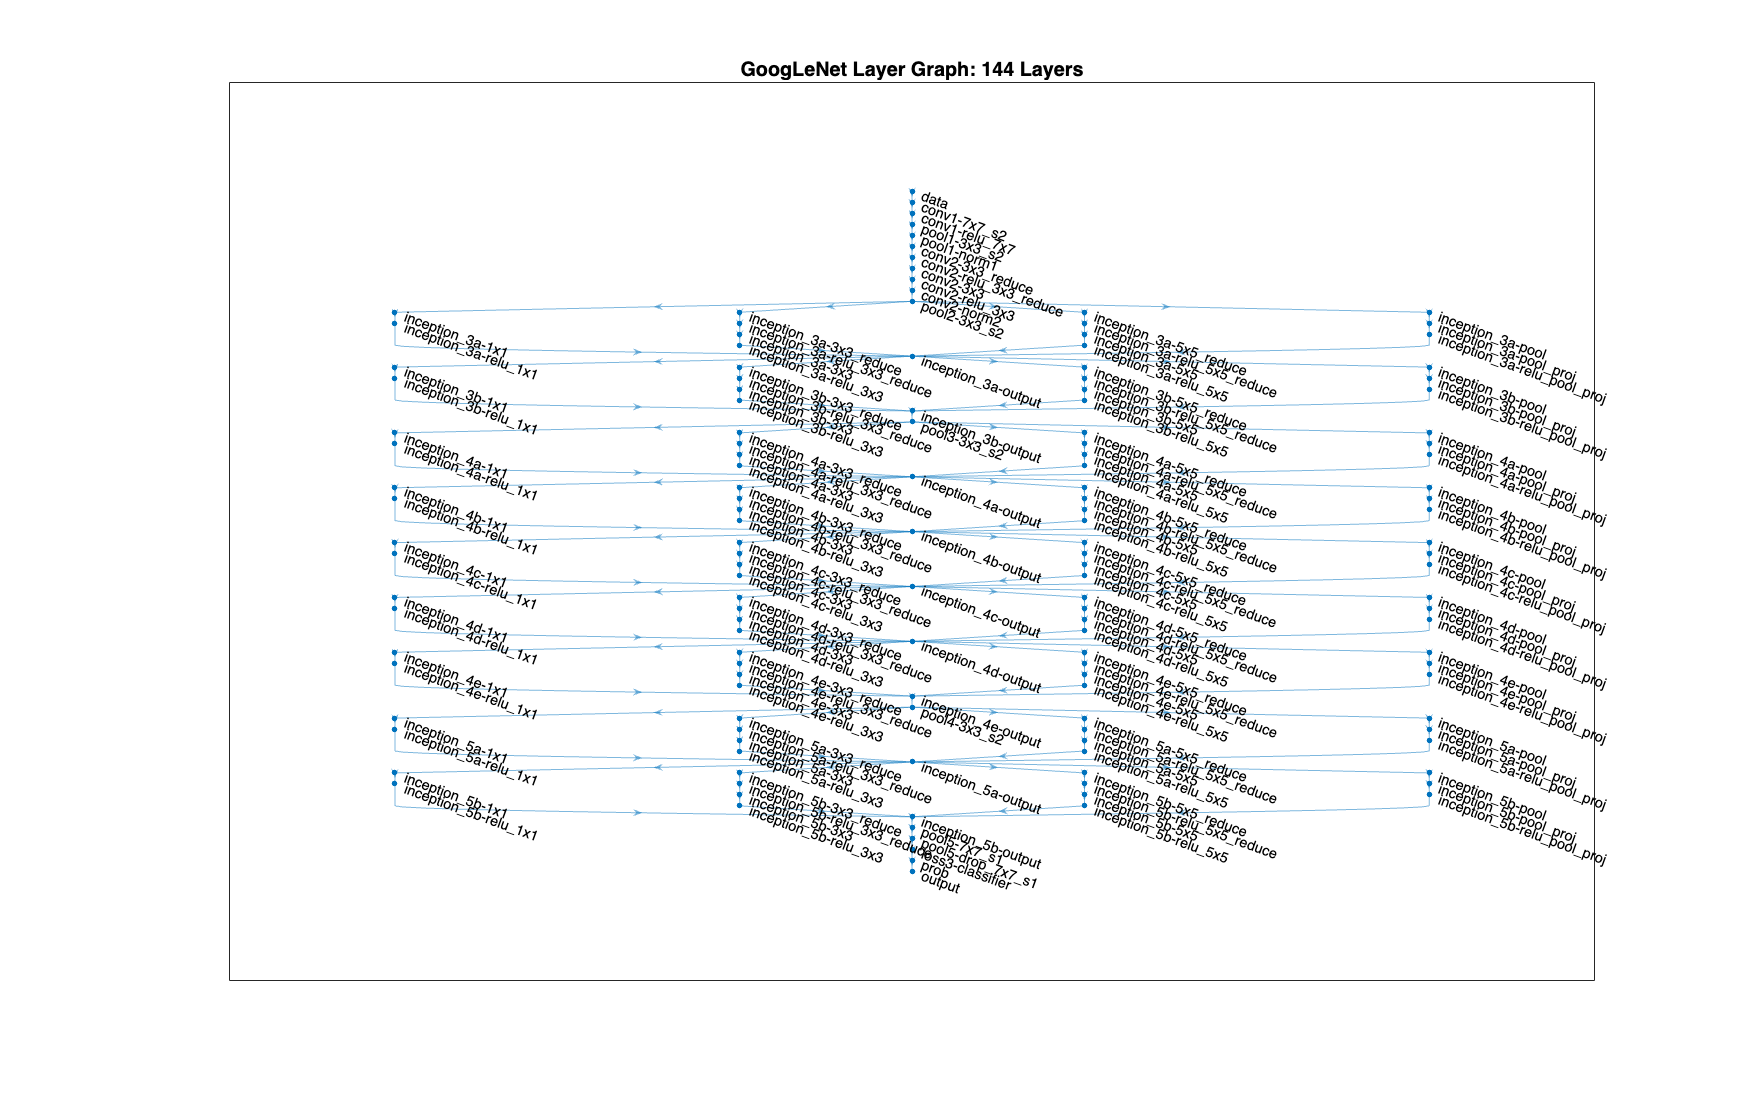


function acc2cwtscg(C_data, cwtfb, signaltype)
    window_size = 1000; % Number of samples to include in each CWT window
    stride = 500; % How many samples to move between each CWT
    colormap = jet(128);

    % Determine the appropriate folder path based on signaltype
    switch signaltype
        case 'sitting'
            folderpath = '/Users/karan/Desktop/Training data/CWTdata/sitting/';
        case 'walking'
            folderpath = '/Users/karan/Desktop/Training data/CWTdata/walking/';
        case 'running'
            folderpath = '/Users/karan/Desktop/Training data/CWTdata/running/';
        otherwise
            error('Invalid signaltype. Must be ''sitting'', ''walking'', or ''running''.');
    end

    % Ensure the folder exists
    if ~exist(folderpath, 'dir')
        mkdir(folderpath);
    end

    % To Get the size of C_data
    [num_samples, ~] = size(C_data);

    % Calculate number of windows
    num_windows = floor((num_samples - window_size) / stride) + 1;


    % Loop through windows
    for i = 1:num_windows
        % Calculate start and end indices for this window
        start_idx = (i-1) * stride + 1;
        end_idx = start_idx + window_size - 1;

        % Extract the signal segment (assuming 3 columns: x, y, z)

numClasses = 3

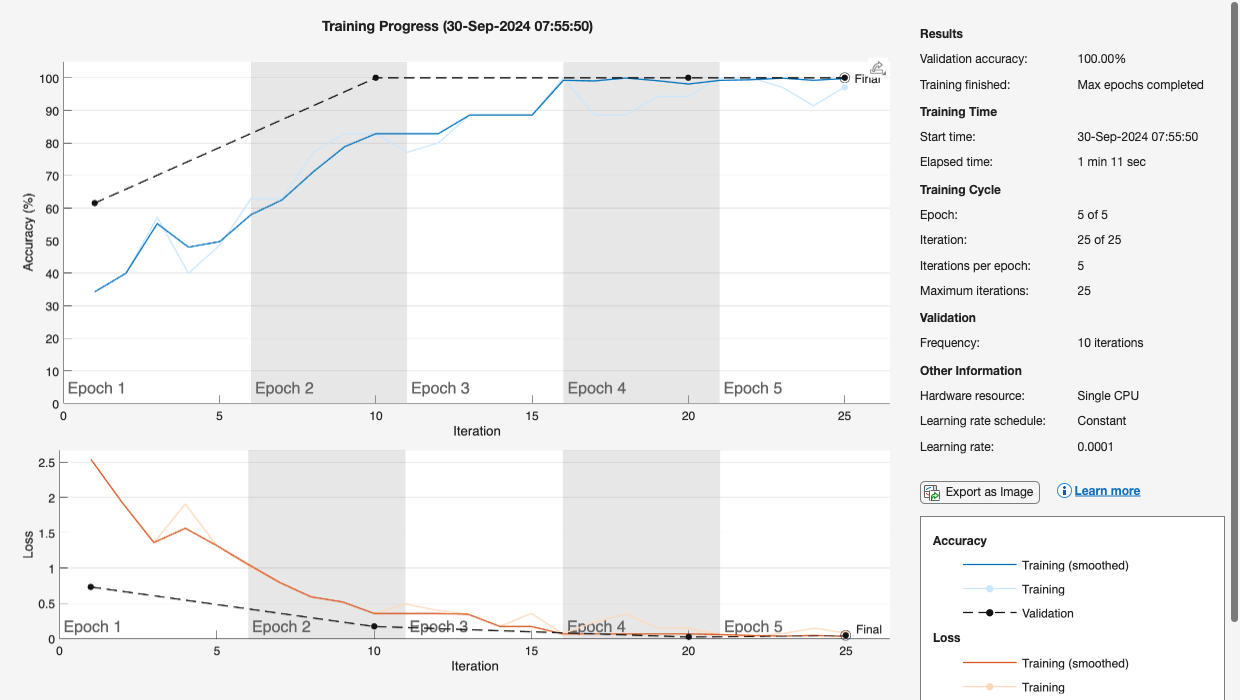

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [running    sitting    walking]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


        accsignal_x = table2array(C_data(start_idx:end_idx, 1));
        accsignal_y = table2array(C_data(start_idx:end_idx, 2));
        accsignal_z = table2array(C_data(start_idx:end_idx, 3));

        % Compute CWT coefficients for each axis
        cfs_x = abs(cwtfb.wt(accsignal_x));
        cfs_y = abs(cwtfb.wt(accsignal_y));
        cfs_z = abs(cwtfb.wt(accsignal_z));

        % Combine CWTs (you might want to adjust this based on your needs)
        cfs_combined = (cfs_x + cfs_y + cfs_z) / 3;

        % Convert to RGB image
        im = ind2rgb(im2uint8(rescale(cfs_combined)), colormap);

        % Generate filename
        filename = fullfile(folderpath, sprintf('%d.jpg', i));

        % Save the image
        imwrite(imresize(im, [227 227]), filename);
    end
end

- **Now we create a  CNN's . In the first case we have Googlenet and we will test the performance and try to achieve good classification results**


%% Data Preparation
DatasetPath = '/Users/karan/Desktop/Training data/CWTdata';
imagescwt = imageDatastore(DatasetPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');


accuracy = 1.0000

% Get the number of files in each label

GoogLeNet cwt Accuracy: 100%


labelCounts = countEachLabel(imagescwt);

% Find the minimum number of files
minFiles = min(labelCounts.Count);

% Distribute images into Training and Testing sets
numTrainFiles = minFiles - 1; % Use the minimum number of files minus 1 for training
[Trainimagescwt, Testimagescwt] = splitEachLabel(imagescwt, numTrainFiles, 'randomized');

%% Network Preparation
net1 = googlenet;

% Create augmented image datastores
inputSize = net1.Layers(1).InputSize;
augtrainimagescwt = augmentedImageDatastore(inputSize(1:2), Trainimagescwt);
augtestimagescwt = augmentedImageDatastore(inputSize(1:2), Testimagescwt);

newsignal = 5×1 timetable
              Time                Z   
    ________________________    ______

    30-Sep-2024 01:18:41.438     5.038
    30-Sep-2024 01:18:41.938    10.604
    30-Sep-2024 01:18:42.438    9.3239
    30-Sep-2024 01:18:42.938    10.014
    30-Sep-2024 01:18:43.438    9.5893



%Extracting and displaying the layer graph from the network.

lgraph = layerGraph(net1);

fb1 =   cwtfilterbank with properties:

      VoicesPerOctave: 15
              Wavelet: "amor"
    SamplingFrequency: 1
       SamplingPeriod: []
         PeriodLimits: []
         SignalLength: 5
      FrequencyLimits: []
        TimeBandwidth: []
    WaveletParameters: []
             Boundary: "reflection"


numberOfLayers = numel(lgraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);


%Modifing GoogLeNet Network Parameters
newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');

Icwtgn =   augmentedImageDatastore with properties:

             NumObservations: 1
                       Files: {'/Users/karan/Desktop/Training data/MobileSensorData/testcwt.jpg'}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);

numClasses = 3;
newConnectedLayer = fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20);


GoogLeNet prediction (cwt) -> ECG Type: sitting, Probability: 99.9522%


lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

%Training the created CNN by feeding the images

%Training Options cwt

optionscwt = trainingOptions('sgdm','minibatchsize',35,'MaxEpochs',5,'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch','ValidationData',Testimagescwt,'ValidationFrequency',10,'Verbose',false, ...
    'Plots','training-progress');

optionsgncwt = trainingOptions('sgdm','minibatchsize',35,'MaxEpochs',5,'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch','ValidationData',augtestimagescwt,'ValidationFrequency',10,'Verbose',false, ...
    'Plots','training-progress');


%training googleNet network
trainedGNcwt = trainNetwork(augtrainimagescwt,lgraph,optionsgncwt);
trainedGNcwt.Layers(end)

Processing sitting: 34276 samples


Processing chunk 1/34 for sitting: [1:1000] samples
Processing chunk 2/34 for sitting: [1001:2000] samples
Processing chunk 3/34 for sitting: [2001:3000] samples
Processing chunk 4/34 for sitting: [3001:4000] samples
Processing chunk 5/34 for sitting: [4001:5000] samples
Processing chunk 6/34 for sitting: [5001:6000] samples
Processing chunk 7/34 for sitting: [6001:7000] samples
Processing chunk 8/34 for sitting: [7001:8000] samples
Processing chunk 9/34 for sitting: [8001:9000] samples
Processing chunk 10/34 for sitting: [9001:10000] samples
Processing chunk 11/34 for sitting: [10001:11000] samples
Processing chunk 12/34 for sitting: [11001:12000] samples
Processing chunk 13/34 for sitting: [12001:13000] samples
Processing chunk 14/34 for sitting: [13001:14000] samples
Processing chunk 15/34 for sitting: [14001:15000] samples
Processing chunk 16/34 for sitting: [15001:16000] samples
Processing chunk 17/34 for sitting: [16001:17000] samples
Processing chunk 18/34 for sitting: [17001:18

Processing walking: 40022 samples


Processing chunk 1/40 for walking: [1:1000] samples
Processing chunk 2/40 for walking: [1001:2000] samples
Processing chunk 3/40 for walking: [2001:3000] samples
Processing chunk 4/40 for walking: [3001:4000] samples
Processing chunk 5/40 for walking: [4001:5000] samples
Processing chunk 6/40 for walking: [5001:6000] samples
Processing chunk 7/40 for walking: [6001:7000] samples
Processing chunk 8/40 for walking: [7001:8000] samples
Processing chunk 9/40 for walking: [8001:9000] samples
Processing chunk 10/40 for walking: [9001:10000] samples
Processing chunk 11/40 for walking: [10001:11000] samples
Processing chunk 12/40 for walking: [11001:12000] samples
Processing chunk 13/40 for walking: [12001:13000] samples
Processing chunk 14/40 for walking: [13001:14000] samples
Processing chunk 15/40 for walking: [14001:15000] samples
Processing chunk 16/40 for walking: [15001:16000] samples
Processing chunk 17/40 for walking: [16001:17000] samples
Processing chunk 18/40 for walking: [17001:18

Processing running: 39961 samples


Processing chunk 1/39 for running: [1:1000] samples
Processing chunk 2/39 for running: [1001:2000] samples
Processing chunk 3/39 for running: [2001:3000] samples
Processing chunk 4/39 for running: [3001:4000] samples
Processing chunk 5/39 for running: [4001:5000] samples
Processing chunk 6/39 for running: [5001:6000] samples
Processing chunk 7/39 for running: [6001:7000] samples
Processing chunk 8/39 for running: [7001:8000] samples
Processing chunk 9/39 for running: [8001:9000] samples
Processing chunk 10/39 for running: [9001:10000] samples
Processing chunk 11/39 for running: [10001:11000] samples
Processing chunk 12/39 for running: [11001:12000] samples
Processing chunk 13/39 for running: [12001:13000] samples
Processing chunk 14/39 for running: [13001:14000] samples
Processing chunk 15/39 for running: [14001:15000] samples
Processing chunk 16/39 for running: [15001:16000] samples
Processing chunk 17/39 for running: [16001:17000] samples
Processing chunk 18/39 for running: [17001:18

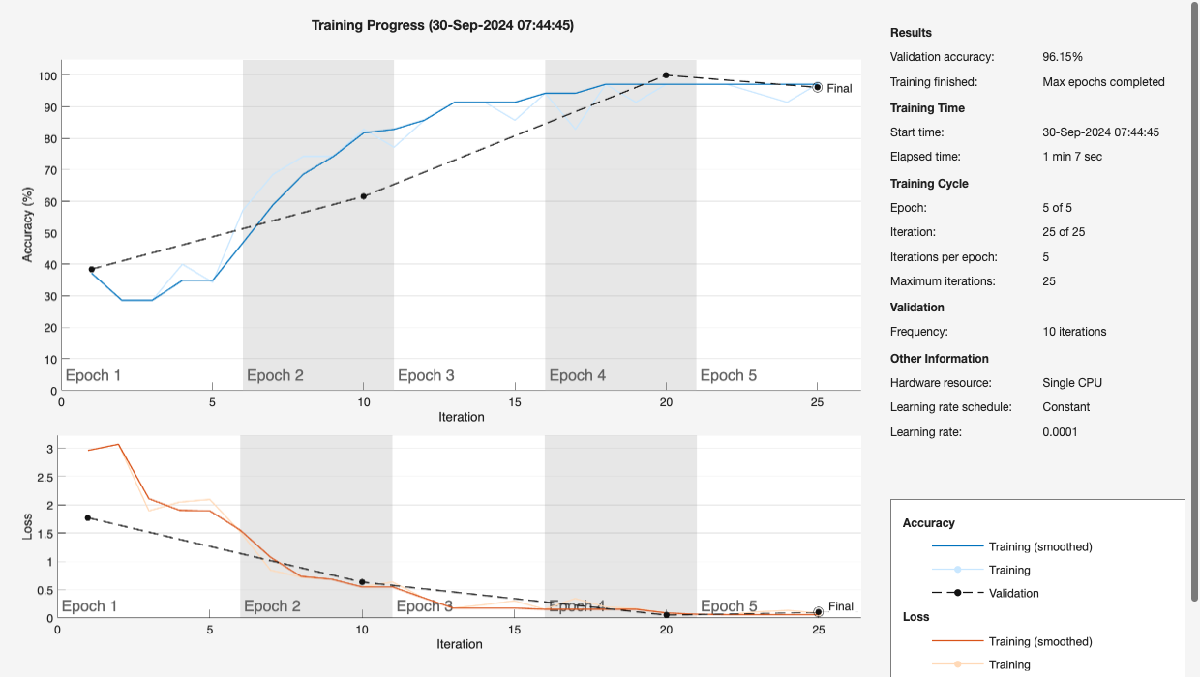

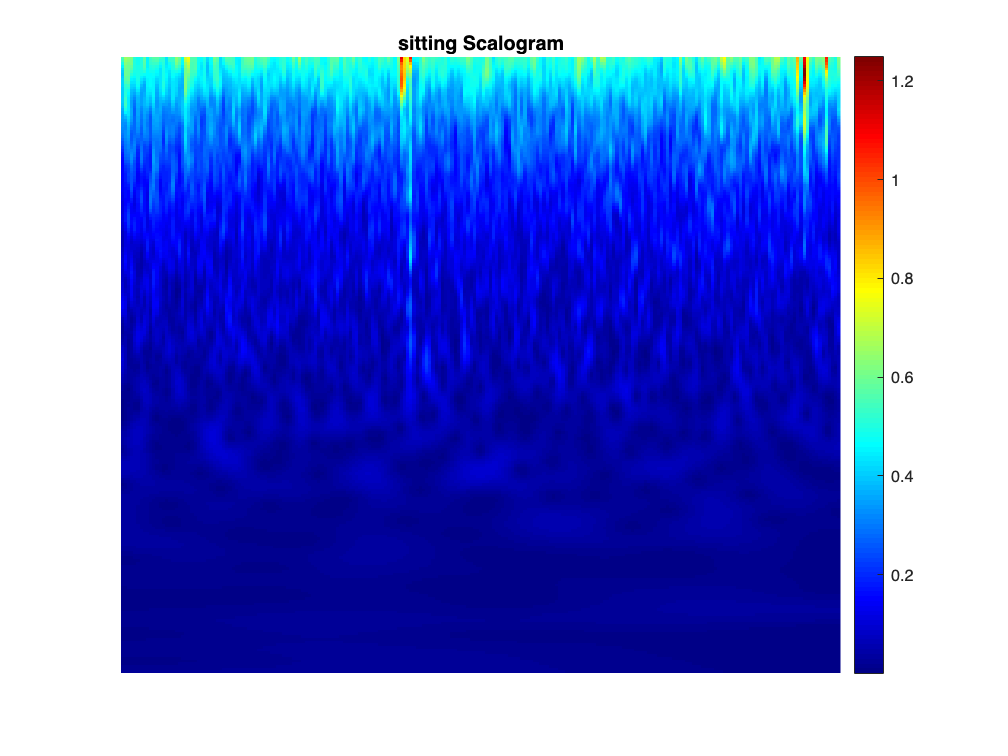

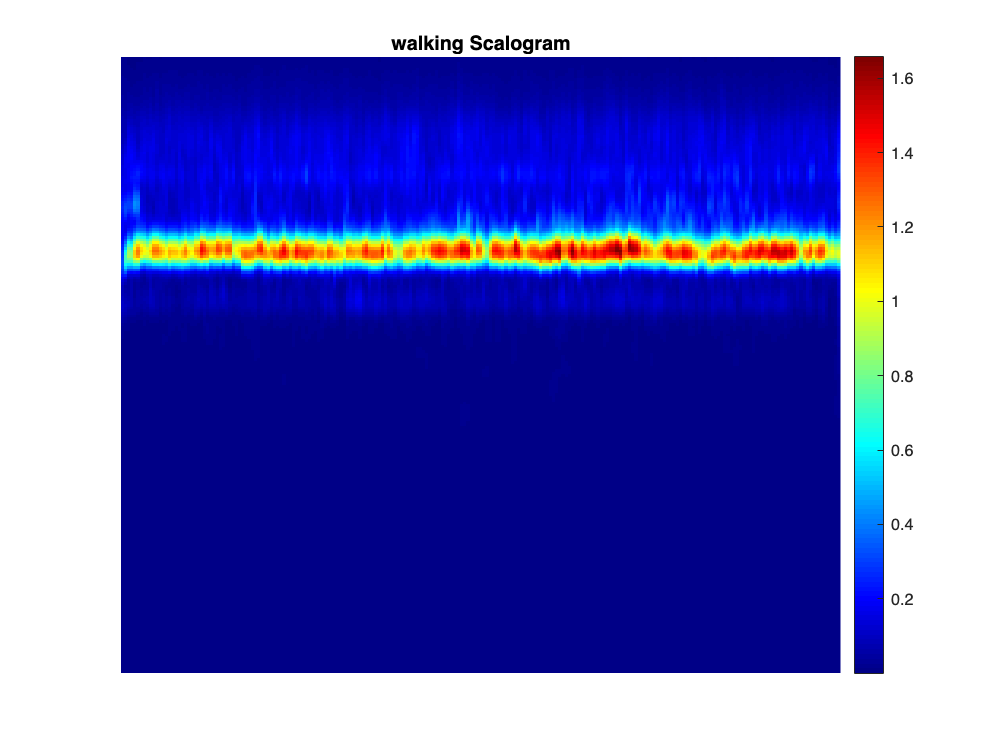

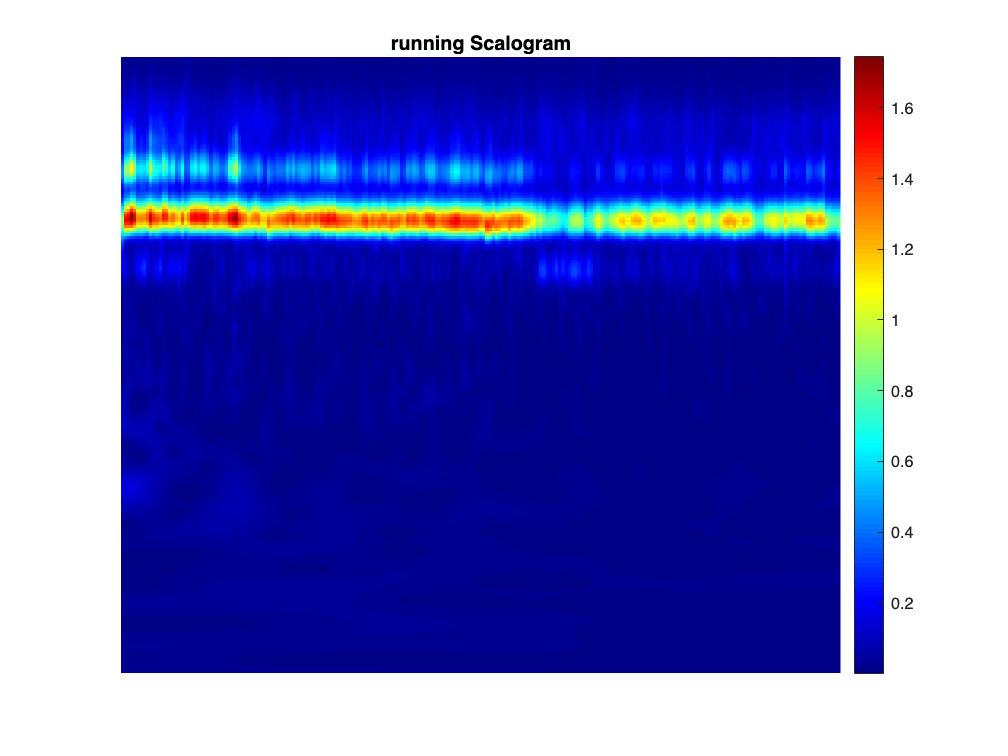


%GoogleNet cwt
YPred = classify(trainedGNcwt,augtestimagescwt);
YValidation = Testimagescwt.Labels;
accuracy = sum((YPred==YValidation)/numel(YValidation))
disp(['GoogLeNet cwt Accuracy: ',num2str(100*accuracy),'%'])

%PLotting the confusion matrix
plotconfusion(YValidation,YPred)

## **Now we test the CNN by using a new dataset**


% testing the created CNN by a test signal
test = load('/Users/karan/Desktop/Training data/MobileSensorData/sitting testset.mat');
signal = test.Acceleration(:, 3);
fs = 60;
p = 2;
q = 2;
resampledSignal = resample(signal, p,q, fs);

%taking first 500 values of signal
newsignal=resampledSignal(1:5,1)

%CWT
%creating rgb image of sample
fb1 = cwtfilterbank('SignalLength',5,'Wavelet','amor','VoicesPerOctave',15)

cfs1 = abs(fb1.wt(table2array(newsignal(:,1))));
im = ind2rgb(im2uint8(rescale(cfs1)),jet(128));
imwrite(imresize(im,[227 227]),'/Users/karan/Desktop/Training data/MobileSensorData/testcwt.jpg');

Icwt = imageDatastore('/Users/karan/Desktop/Training data/MobileSensorData/testcwt.jpg'); 

Icwtgn = augmentedImageDatastore([224 224],Icwt)  %for googlenet

%Printing the output with prediction percentage with the class for prediction 

[Prediction,Probability] = classify(trainedGNcwt,Icwtgn);
disp(['GoogLeNet prediction (cwt) -> ECG Type: ' char(Prediction) ', Probability: ' num2str(100*max(Probability)) '%'])


`IN order to re-validate the classification accuracy of our CNN. WE have used a input signal named as "newsignal" and the result output from CNN is shown as below.`

`GoogLeNet prediction (cwt) -> ECG Type: sitting, Probability: 99.9524%`

`Now using an alternate CNN we try to achieve similar results.`

% Scalogram resizing for CNN for creating dataset for the second CNN
imgSize = [227 227];
numActivities = numel(C_Accel);
resizedScalograms = [];
labelsArray = {};
minLength = 1000;

`Generating individual scalograms for each activity using Continuous wavelet Transform CWT`

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       21.88% |       42.86% |       3.5487 |       3.2474 |          0.0005 |
|      10 |          10 |       00:01:02 |      100.00% |       97.14% |   0.0000e+00 |       2.2710 |          0.0005 |
|      20 |          20 |       00:01:59 |      100.00% |       97.14% |   0.0000e+00 |       2.7695 |      5.0000e-05 |
|      30 |          30 |       00:02:52 |      100.00% |       97.14% |   0.0000e+00 |       2.9393 |      5.0000

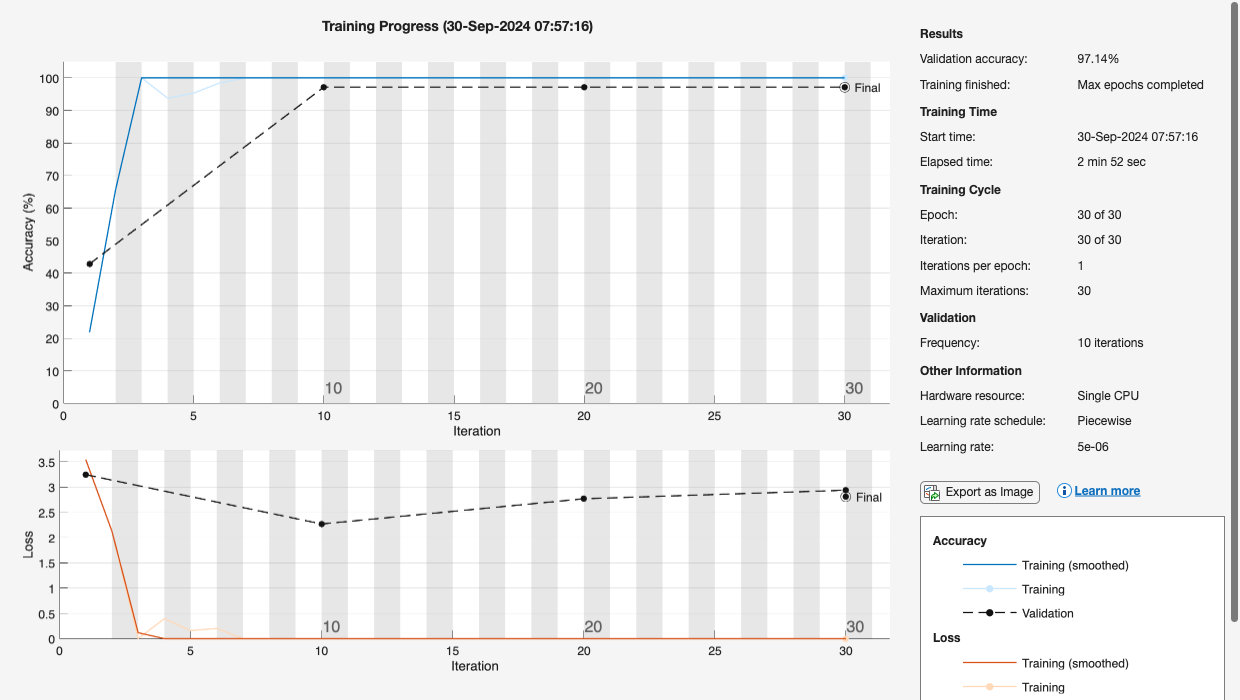

% Generate scalograms
for i = 1:numActivities
    sampleData = C_Accel{i};
    numSamples = numel(sampleData);
    
    fprintf('Processing %s: %d samples\n', signaltype{i}, numSamples);
    
    % Check if data is long enough
    if numSamples >= minLength
        % Calculate number of chunks
        numChunks = floor(numSamples / minLength);
        
        for j = 1:numChunks
            startIdx = (j-1) * minLength + 1;
            endIdx = j * minLength;
            chunkData = sampleData(startIdx:endIdx);
            
            % Debugging info about the chunk being processed

            fprintf('Processing chunk %d/%d for %s: [%d:%d] samples\n', j, numChunks, signaltype{i}, startIdx, endIdx);
            
            % Continuous wavelet transform (CWT) using 'morse' wavelet
            try
                [cfs, ~] = cwt(chunkData, 'amor', fs);  % Ensure fs is defined
                scaledImage = imresize(abs(cfs), imgSize, 'bilinear');
                
                % Concatenate along the 4th dimension (for CNN input)

                resizedScalograms = cat(4, resizedScalograms, scaledImage);
                
                % Append label
                labelsArray = [labelsArray; {signaltype{i}}];
            catch ME
                % Display more information about the error
                warning('Error processing chunk %d of %s: %s', j, signaltype{i}, ME.message);
            end
        end
    else
        warning('Data for %s too short. Skipping...', signaltype{i});
    end
end
% After processing, visualize and save the scalograms in a defined
% directory
for i = 1:numel(C_Accel)
    sampleData = C_Accel{i};
    
    % Continuous wavelet transform (CWT) with 'morlet' wavelet
    [cfs, ~] = cwt(sampleData, 'amor', fs);
    
    % Create and resize scalogram image
    scalogramImage = abs(cfs);
    scaledImage = imresize(scalogramImage, imgSize, 'bilinear');

    % Plot the scalogram for visualization
    figure;
    imagesc(scaledImage);
    axis off;
    colormap jet(128);
    colorbar;
    title([signaltype{i} ' Scalogram']);

    % Save the image to a folder (ensure the directory exists)
    saveas(gcf, ['/Users/karan/Desktop/Training data/Alternate CNN/' signaltype{i} '_Scalogram.png']);
    
    % Store scalograms and labels for CNN input
    resizedScalograms = cat(4, resizedScalograms, scaledImage);
    labelsArray = [labelsArray; {signaltype{i}}];
end

% Convert labels to categorical
categoricalLabels = categorical(labelsArray);

`Now we shuffle the data using a random permutation and also Splitting the data into training and testing sets.`

% Shuffle the data
rng(0);
totalSamples = numel(categoricalLabels);
shuffleIdx = randperm(totalSamples);
resizedScalograms = resizedScalograms(:,:,:,shuffleIdx);
categoricalLabels = categoricalLabels(shuffleIdx);
% Split into training and testing sets
trainRatio = 0.7;
numTrain = round(trainRatio * totalSamples);
numTest = totalSamples - numTrain;

trainImgs = resizedScalograms(:,:,:,1:numTrain);
trainLabels = categoricalLabels(1:numTrain);
testImgs = resizedScalograms(:,:,:,numTrain+1:end);
testLabels = categoricalLabels(numTrain+1:end);

`Defining CNN Architecture in totality`

% Updated CNN architecture with residual block and tuned hyperparameters
layers = [
    imageInputLayer([imgSize 1], 'Name', 'input')

    convolution2dLayer(3, 32, 'Padding', 'same', 'WeightsInitializer', 'he', 'Name', 'conv_1')
    batchNormalizationLayer('Name', 'batchnorm_1')
    reluLayer('Name', 'relu_1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool_1')

    convolution2dLayer(3, 64, 'Padding', 'same', 'WeightsInitializer', 'he', 'Name', 'conv_2')
    batchNormalizationLayer('Name', 'batchnorm_2')
    reluLayer('Name', 'relu_2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool_2')

    convolution2dLayer(3, 128, 'Padding', 'same', 'WeightsInitializer', 'he', 'Name', 'conv_3')
    batchNormalizationLayer('Name', 'batchnorm_3')
    reluLayer('Name', 'relu_3')

    % Residual Block
    convolution2dLayer(3, 128, 'Padding', 'same', 'WeightsInitializer', 'he', 'Name', 'conv_4')
    batchNormalizationLayer('Name', 'batchnorm_4')
    reluLayer('Name', 'relu_4')

    convolution2dLayer(3, 128, 'Padding', 'same', 'WeightsInitializer', 'he', 'Name', 'conv_5')
    batchNormalizationLayer('Name', 'batchnorm_5')

    additionLayer(2, 'Name', 'add')
    reluLayer('Name', 'relu_5')

    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool_3')

    fullyConnectedLayer(128, 'Name', 'fc_1')
    dropoutLayer(0.5, 'Name', 'dropout') % Slightly reduced dropout rate
    fullyConnectedLayer(numel(unique(categoricalLabels)), 'Name', 'fc_2')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')];

% Layer graph to handle residual connection
lgraph = layerGraph(layers);

% Adding skip connection for the residual block
lgraph = connectLayers(lgraph, 'relu_3', 'add/in2');  % Connecting skip connection from 'relu_3' to 'add/in2'

% Training options
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 64, ...
    'MaxEpochs', 30, ...
    'InitialLearnRate', 5e-4, ...  % Adjusted learning rate
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 10, ...
    'ValidationData', {testImgs, testLabels}, ...
    'ValidationFrequency', 10, ...
    'L2Regularization', 1e-4, ...
    'Verbose', 1, ...
    'ExecutionEnvironment', 'cpu', ...
    'Plots', 'training-progress');

`Again we train the created CNN`

% Train the CNN
rng default
net = trainNetwork(trainImgs, trainLabels, lgraph, options);

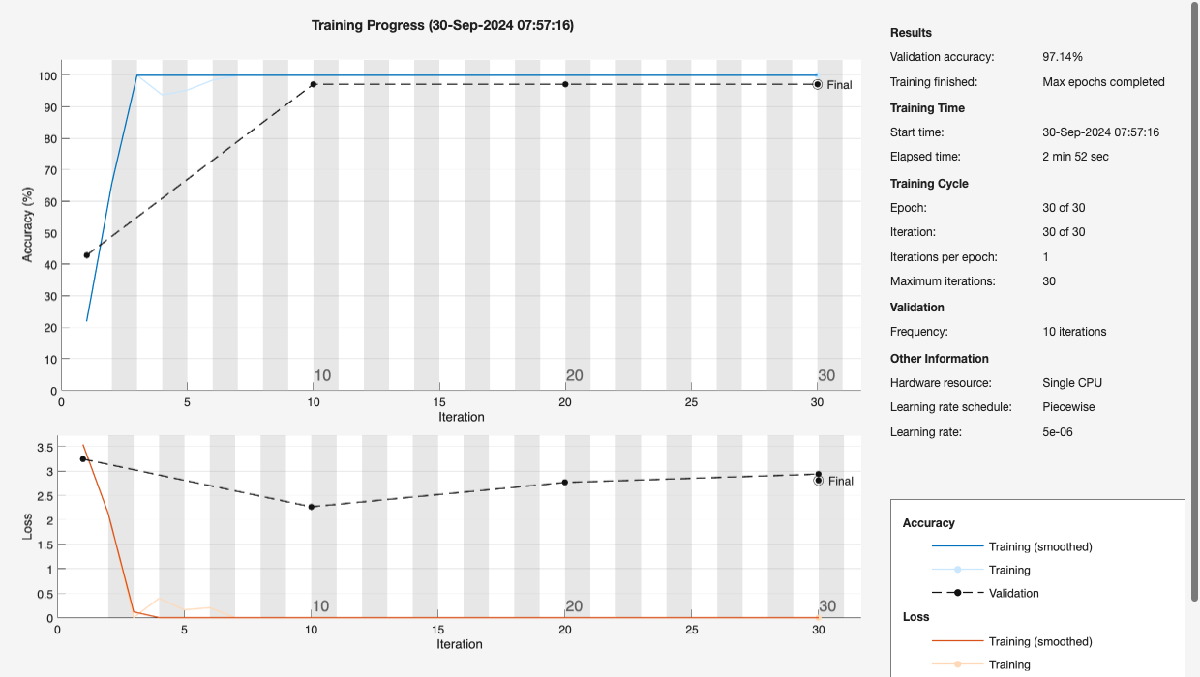

`Performance evaluation on test data`

% Confusion matrix
confMat = confusionmat(testLabels, predictedLabels);
fig = figure;
plotconfusion(testLabels,predictedLabels);
title('Confusion Matrix');
saveas(fig, 'ConfusionMatrix.png');